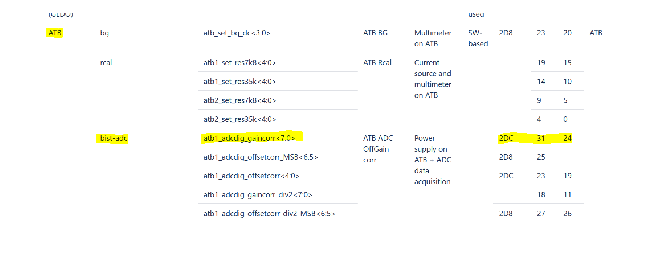

imshow(imread('C:\Users\nxf59937\Desktop\otpAtbGain.PNG'))

% Number of bits used for the OTP value
N = 8

N =      8


% Value read from OTP via proxy
registerValue_Decimal = 3624870044

registerValue_Decimal =                 3624870044


registerValue_Binary  = dec2bin(registerValue_Decimal)

registerValue_Binary = '11011000000011110010000010011100'

% OTP trimming value is in bits 31 till 24, least 23 bits are useless (
% 23th till 0 bit)
trimvalue_Binary  = dec2bin(bitshift(registerValue_Decimal,-24))

trimvalue_Binary = '11011000'

trimvalue_Decimal = bin2dec(trimvalue_Binary)

trimvalue_Decimal =    216


% Convert to uint16
trimvalue_uint16 = typecast(uint32(trimvalue_Decimal),'int16')

trimvalue_uint16 = 1×2 int16 row vector
   216     0


% Convert to int16
trimvalue_int16 = typecast(uint16(trimvalue_uint16(1)),'int16')

trimvalue_int16 = int16
   216


% Check whether trim value is greater than INT8_MAX, meaning negative
% number
isNegative = trimvalue_int16(1) > (2^(N-1))

isNegative = logical
   1


% Check bit_8th is 1, if 1 number is negative
bit_8th = bitget(trimvalue_Decimal,8)

bit_8th =      1


if bit_8th == 1
    % Convert from 2's complement to signed value as x = x's2Complement -
    % 2^8
    trimvalue_int16 = trimvalue_int16(1) - (2^N)
end

trimvalue_int16 = int16
   -40


% Convert to int16
trimvalue_int8 = typecast(int16(trimvalue_int16),'int8');
trimvalue_int8 = trimvalue_int8(1)

trimvalue_int8 = int8
   -40
